# Tutorial:  Curve Fitting

NM 2021

# Part 1: Linear Least Square Regression

## Problem Statement

An experiment is conducted that measures the pressure of a gas by heating it in a closed chamber. 

T=[30	40	50	60	70	80];

P=[1.05	1.07	1.09	1.14	1.17	1.21];

### Predict the pressure if the temperature is increased to 150C.

based on Charles's law for ideal gas

P=kT, where k is a constant.

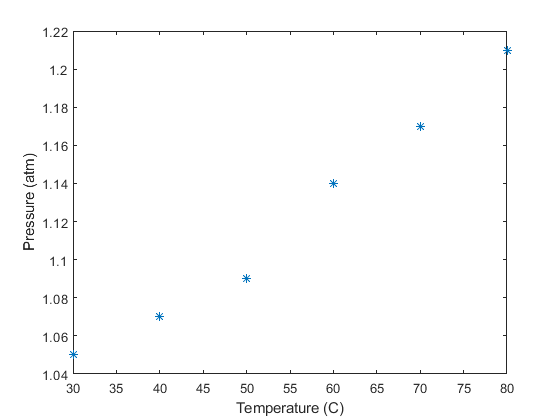

close all, clear all

T=[30	40	50	60	70	80];
P=[1.05	1.07	1.09	1.14	1.17	1.21];
figure(1)
plot(T,P, '*')

xlabel('Temperature (C)')
ylabel('Pressure (atm)')

### Using Matlab Function

The best fit curve is   P=a0+a1(T)

a=polyfit(T,P,1)

a =     0.0033    0.9410


Plot the best-fit linear function 

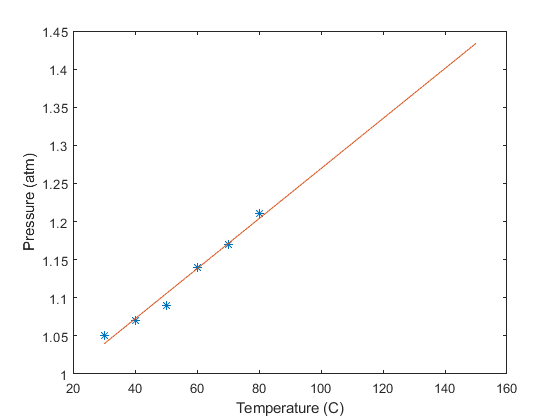

t=30:10:150;
yhat=a(2)+a(1).*t;
figure(2)
plot(T,P, '*')
hold on
plot(t,yhat)
xlabel('Temperature (C)')
ylabel('Pressure (atm)')

## Revision

Linear Least Square Regression formula 

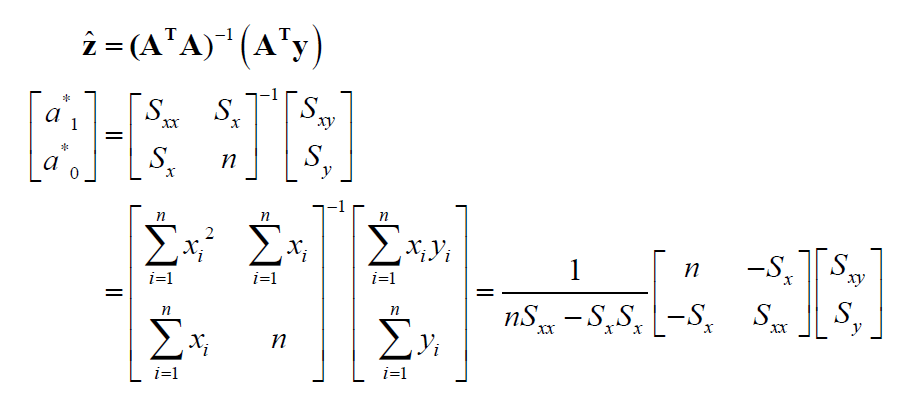

### Thus, we will use the following formula to find the optimal fit line parameters.

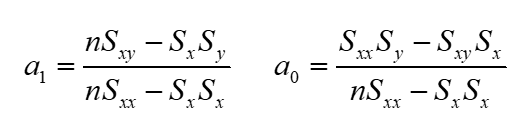

# Exercise

Create a function that returns the parameters of the linear least square function.

close all, clear all

x=[30	40	50	60	70	80];
y=[1.05	1.07	1.09	1.14	1.17	1.21];

z=linearFit(x, y) 

z =     0.0033    0.9410


%z=linearFit_student(x, y) 

## Process

#### **First, create the function's definition here. **

 Input data sets of (x, y):  # m data sets

    %   1-1. Check if the number of dataset is less than 2. (  m<2 )

    %   1-2. Check if length(X)~= length(Y) ? Exit: Continue 

    mx = length(x);
    my = length(y);  

    % ADD YOUR CODE         
    % ADD YOUR CODE         

    %   2. Initialize Sx, Sxx, Sy, Sxy

    Sx=0; Sxx=0; Sxy=0;Sy=0;  

    %   3. Solve for Sx, Sxx, Sy, Sxy,  for k=1 to m

    % ADD YOUR CODE         
    % ADD YOUR CODE        

    %   4. Solve for a1, a2

    % ADD YOUR CODE         
    % ADD YOUR CODE        

    %   5. Return z=[a1, a0]

    z=[a1, a0];

#### **Then, Create the function as a separate file as 'linearFit.m'**

Now, Create 'C' program  code for linearFit()

# Part 2:  Polyfit

### Using Least Square regression formula for high-order polynomial

close all, clear all

x=[30	40	50	60	70	80];
y=[1.05	1.07	1.09	1.14	1.17	1.21];

z=myPolyfit(x, y,3) 

S = 	1.0e+11 *

    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0009
    0.0000    0.0000    0.0009    0.0617
    0.0000    0.0009    0.0617    4.4690


b = 	1.0e+06 *

    0.0000
    0.0004
    0.0230
    1.5002


z =    -0.0000    0.0002   -0.0074    1.1376


% Check with MATLAB output
zmatlab=polyfit(x,y,3)

## Process

#### **First, create the function's definition here. **

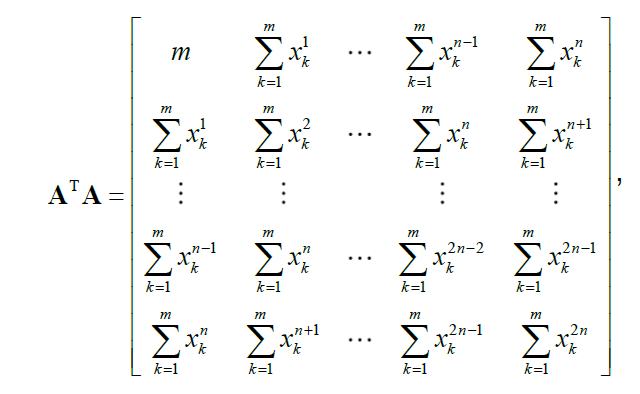

% # of datasets: m

%  (n)th order polynomial:  (n+1) unknowns

% A: (m) by (n+1) //  A'A: (n+1) by (n+1)

% Polynomial order ...+(a4)x^4+(a3)x^3+...+(a1)x+a0.

    % Input parameter:  x, y, n
    n=3;

    %   1-1. Check if length(X)~= length(Y) ? Exit: Continue 

    %   1-2. Check if   m<(n+1) ? Exit: Continue 

    mx = length(x);
    my = length(y);  

    % ADD YOUR CODE         
    % ADD YOUR CODE         

    %   2. Initialize S, b, z

    Pcoef=zeros(1,n+1);
    S=zeros(n+1,n+1);
    b=zeros(n+1,1);
    z=zeros(1,n+1);

    % 3.  SX(i)=sum(x.^(i)), for i=0 to 2n  #(2n+1)

    % ADD YOUR CODE         
    % ADD YOUR CODE        
    % ADD YOUR CODE        
    % ADD YOUR CODE     

%   4. Create matrix A'A from SX

    % ADD YOUR CODE        
    % ADD YOUR CODE   

%  5. Construct vector b=(A'y) as

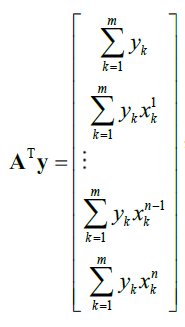

    % ADD YOUR CODE         
    % ADD YOUR CODE        

 %  6. Calculate for optimal Z=inv(S)*(b)

 % where z=[a(0), a(1), a(2),.... a(n)] , (n+1)x1

    % ADD YOUR CODE         
    % ADD YOUR CODE    

 %   7-1.  Return z=[a0, a1, ....];

 %  7-2   If need to return coefficent as    Pcoef=[....a4 a3 a2 a1 a0]

    for i = 1:n+1
        Pcoef(i) = z(n+1-i+1);
    end

Now, try  make the algorithm more efficient. 